# Lab 5

# Section 1

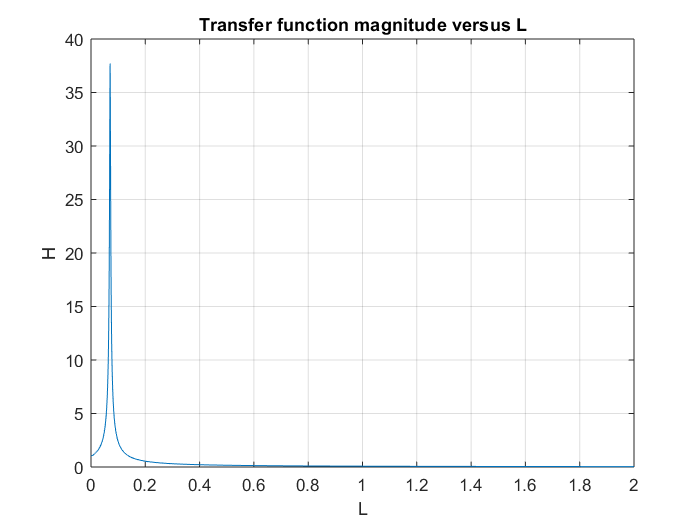

% Define the constant
R = 1000; % ohms
C = 100e-6; % capacitor
L = 0:1e-6:2;
s = 2*pi*60*1i;
num = [s R]; % numerator
den = [C*s^3 R*C*s^2+2*s R]; % denominator
H_s = polyval(num,L)./polyval(den,L);
% Plot transfer function magnitude versus L
mag_H = abs(H_s);
figure
plot(L,mag_H)
title('Transfer function magnitude versus L')
xlabel('L');ylabel('H')
grid on

#### **Find L**

min_diff = min(abs(mag_H-0.1)); % find the closest value to 0.1
ind = find(abs(mag_H-0.1)==min_diff);
L = L(ind(1))

L =    0.779315000000000


# Section 2

**(a)**

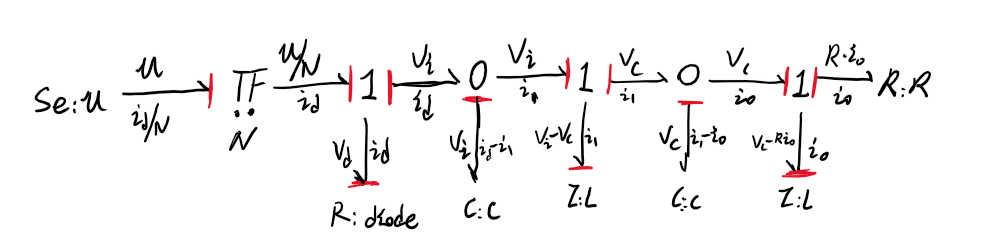

**(b)**

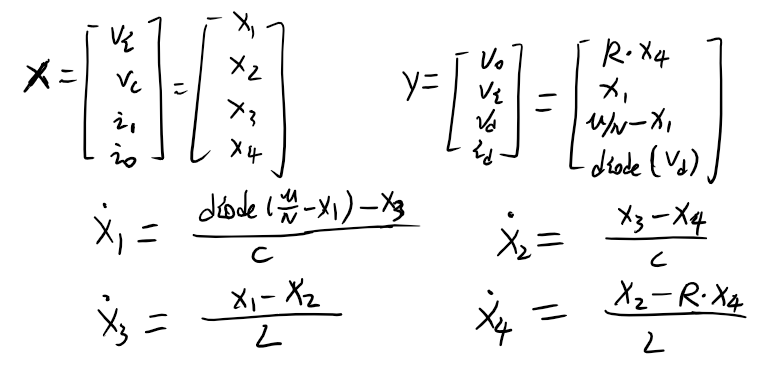

**(c)**

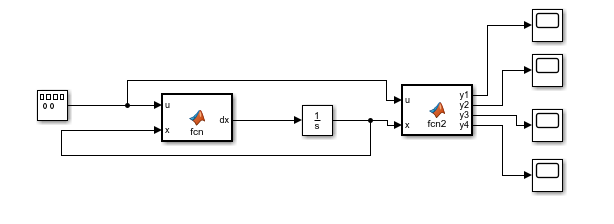

**(d)**

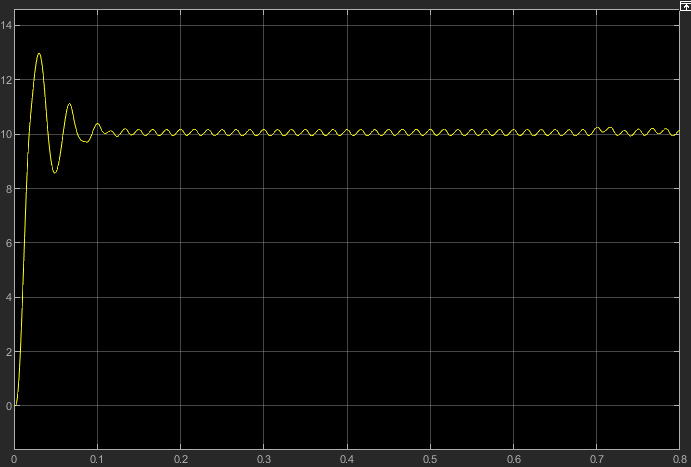

**figure 3: plot for y1**

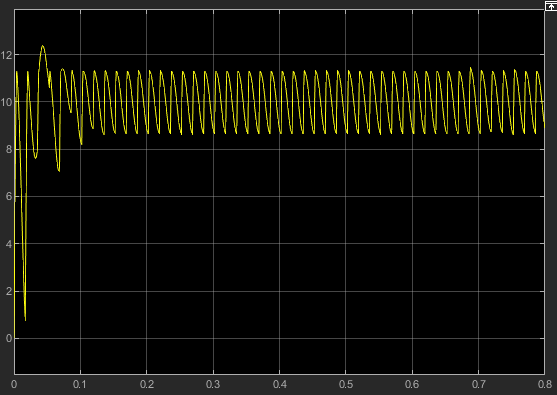

**figure 4: plot for y2**

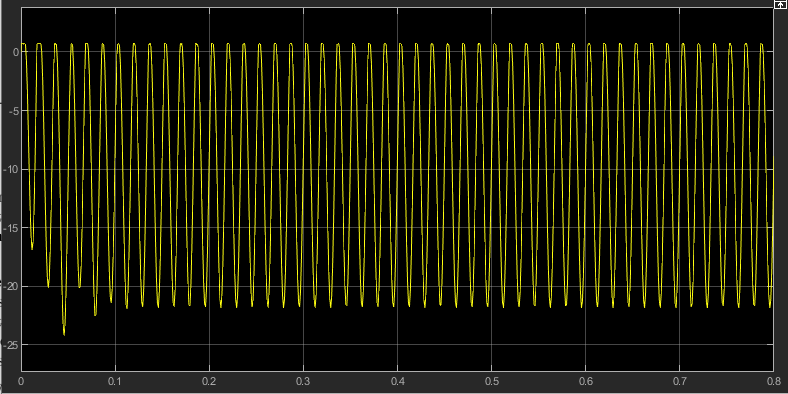

**figure 5: plot for y3**

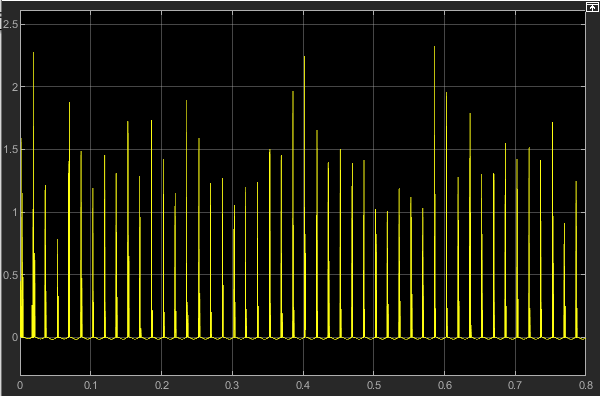

**figure 6: plot for y4**

We can observe: 

The diode ensures that the current through it is only positive; 

The capacitor charges during the first cycle, has a transient that decays away within 0.1 second, then maintains a steady-state oscillation of 3.2 volts (peak-to-peak by zooming in figure 4); 

The output voltage across the resistor Vo is  .3 volts (peak-to-peak by zooming in figure 3). 

Therefore, the sequence of energy storage devices (capacitors and inductors) have done their job of reducing the voltage oscillation by a factor of 10.6, which exceeds the spec of 10%. Success!

**(e)**

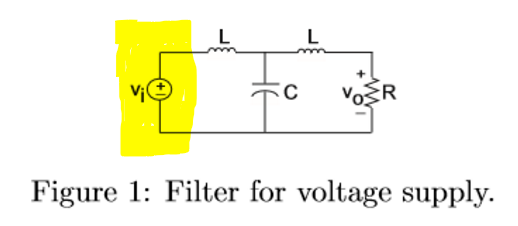  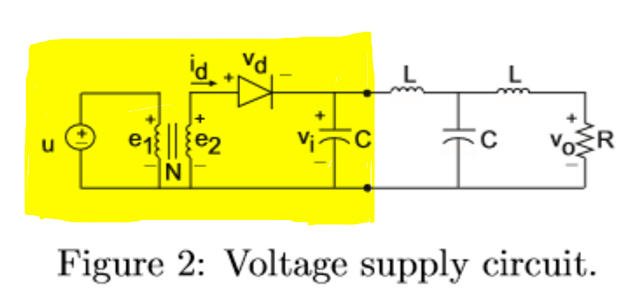

Now we consider the circuit in Figure 1 as having two subsystems, with the highlighted portion on the left acting as one system and the other half of the system acting as another subsystem. The system that is highlighted serves as a positive voltage source that is stepped down from that of the 120 V input. We can see this in the Vi plot in Figure 3 & 4. Figure 2 shows how thinking about this subsystem as a voltage source Vi, can greatly simplify the system. 

The subsystem on the right is there to provide a steady and stable output voltage. This can be seen by observing the Figure 3 and 4 graphs. We can see the voltage is now oscillating very little and is supplying an almost constant 10 Volts when compared to the initial input. 

The purpose of the diode is to only allow current to flow in one direction, which only happens when the voltage is greater than 0.7 V. The transformer steps down the voltage, while the inductors and capacitors store energy to stabilize the current through the resistive load. Together, we have created a stable DC Source out of 120 V AC input.  To further and dramatically stabilize the voltage, a solid state voltage regulator could be used in place of the LCL sequence of energy storage elements. 

**(f)**

By varying the resistance of our R value, the output oscillations vary as well. The corresponding Voltage Percent Variation changes can be seen in the table below. 

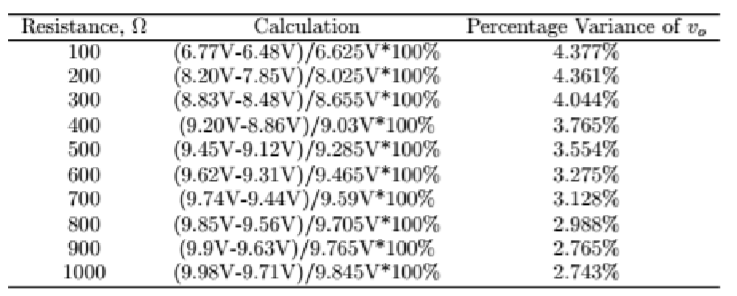

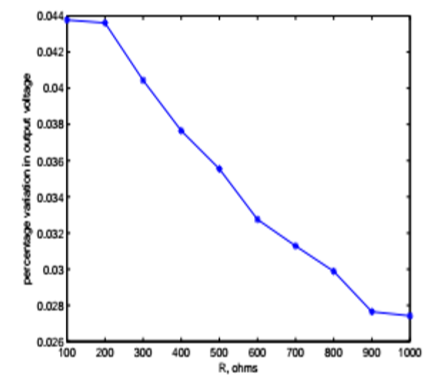

we can see that as the resistance of the load increases the percent variation of the output voltage also increase. So the bigger the load, the less variance we have in the output voltage. 